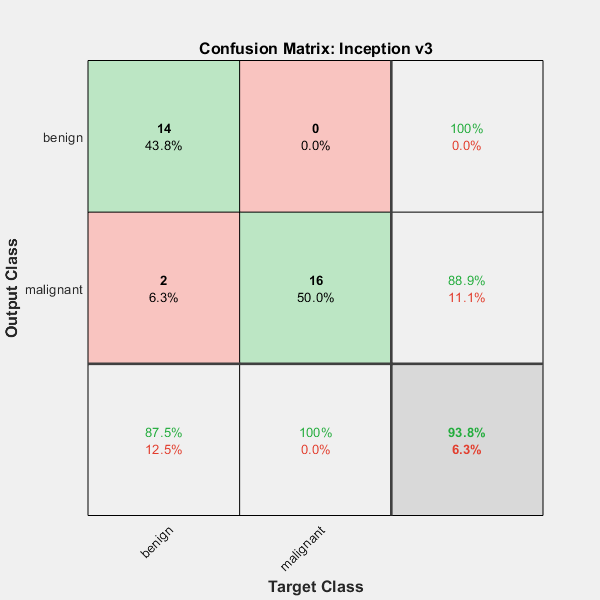

load mini_date2.mat
% Reshape the test images match with the network 
augimdsValidation = augmentedImageDatastore([224 224],imdsValidation);

% Predict Test Labels
[predicted_labels,posterior] = classify(netTransfer,augimdsValidation);

% Actual Labels
actual_labels = imdsValidation.Labels;

% Confusion Matrix
figure
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix: Inception v3');

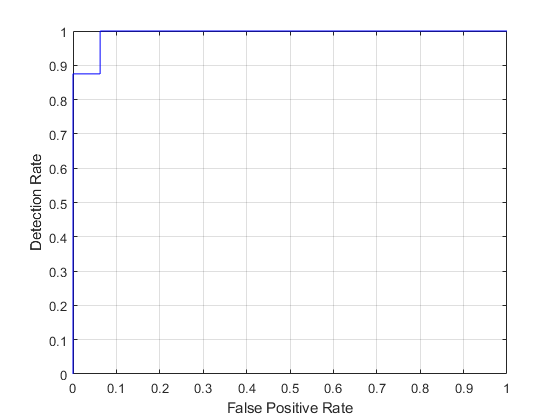

% Curba ROC
validation_labels=double(nominal(imdsValidation.Labels));
[fp_rate,tp_rate,T,AUC] = perfcurve(validation_labels,posterior(:,2),2);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');